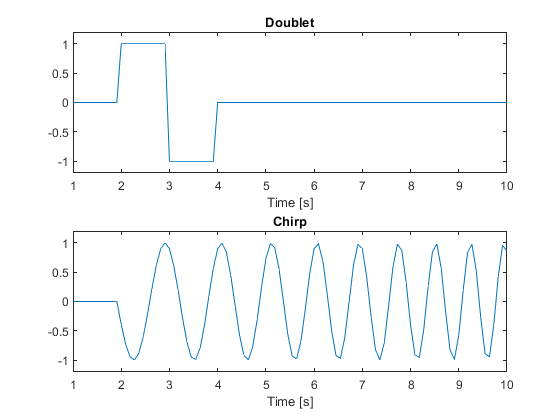

t = linspace(1,10,100);

y1 = zeros(1,size(t,2));
y1(and(t>=2,t<3)) = 1;
y1(and(t>=3,t<4)) = -1;
y = zeros(1,size(t,2));

t2 = linspace(2,10,90);
y2 = [y(t<1.9),chirp(t2,0.512,10,1.5,"linear",10)];

figure(1)
clf
ax1=subplot(2,1,1);
plot(t,y1)
ylim([-1.2,1.2])
title("Doublet")
xlabel("Time [s]")

ax2=subplot(2,1,2);
plot(t,y2)
ylim([-1.2,1.2])
title("Chirp")
xlabel("Time [s]")
linkaxes([ax1,ax2],'x');